## **Ejemplo de Matlab**

rng('default'); % For reproducibility
n = 20;
X = [randn(n,2)*0.5+3;
    randn(n,2)*0.5;
    randn(n,2)*0.5-3];

[~,V_temp,D_temp] = spectralcluster(X,5);

D_temp

D_temp =    -0.0000
   -0.0000
   -0.0000
    0.0876
    0.1653


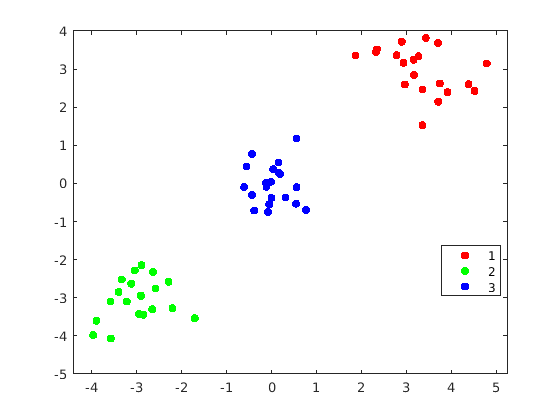

[a,b] = find(D_temp<1e-3);

k = sum(b);
[idx1,V,D] = spectralcluster(X,k);
gscatter(X(:,1),X(:,2),idx1);

## Clusterización con un ejemplo de nichos

----Reading layers----


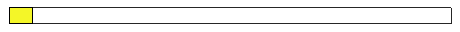

Elapsed time is 13.721061 seconds.


addpath Tool/VirtualSpeciesFunctions/
addpath Tool/
layerfolder = "Capas/Capas_SouthAmerica_2.5M/"; %route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

load("Clustering/T500.mat")
% load("Clustering/T.mat")

data1 = bnm_prep(T, Dimensions, false, 0.7);

----Finding correlation----
----Finding correlation----
Elapsed time is 6.643379 seconds.
----Creating predictors----
¡All done!
----Finding correlation----


Error using bnm_prep (line 86)
Variable index exceeds table dimensions.

        % modeling, save Metric
% data = bnm_modeling(data1, '', true); 

load("Clustering/T_bio500.mat")
% load("Clustering/T_bio.mat")

X = table2array(T(:,2:3));
[~,V_temp,D_temp] = spectralcluster(X,10,'Distance',"chebychev");

D_temp

D_temp =     0.0000
         0
         0
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0336
    0.0362


Obtener orden de magnitud

n = floor(log(abs(D_temp))./log(10))

n =    -25
  -Inf
  -Inf
   -26
   -18
   -18
   -18
   -17
    -2
    -2


INF = isinf(n);
n(INF) = 0;
k = find(n<=min(n)+5)

k =      1
     4


k=length(k)+sum(INF)

k = 4

[idx1,V,D] = spectralcluster(X,k);

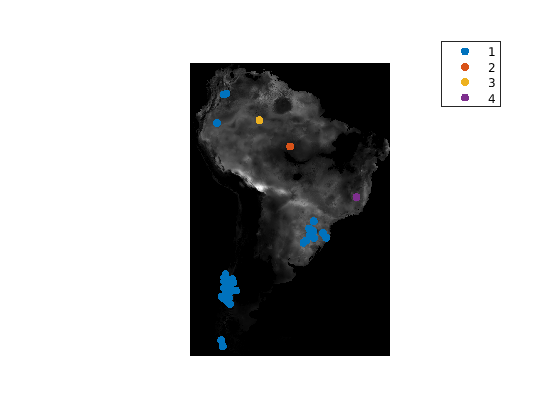

figure
colormap(gray(256))
geoshow(data.Map,Dimensions.R,'DisplayType','texturemap')
hold on

load carsmall
color = lines(6); % Generate color values

gscatter(T.LONG,T.LAT, idx1,color(1:6,:));
hold on
axis off